
=== Vibration Analysis (PD) ===
omega_n = 70.7107 rad/s | f_n = 11.2540 Hz | zeta = 0.7071
PD gains: Kp = 1000 N/m, Kd = 0 Ns/m

--- Peak metrics (magnitude) ---
x_peak = 0.001 m at t=0 s (signed: 0.001)
v_peak = 0.0440694 m/s at t=0.0136278 s (signed: -0.0440694)
a_peak = 7.5 m/s^2 at t=0 s (signed: -7.5)


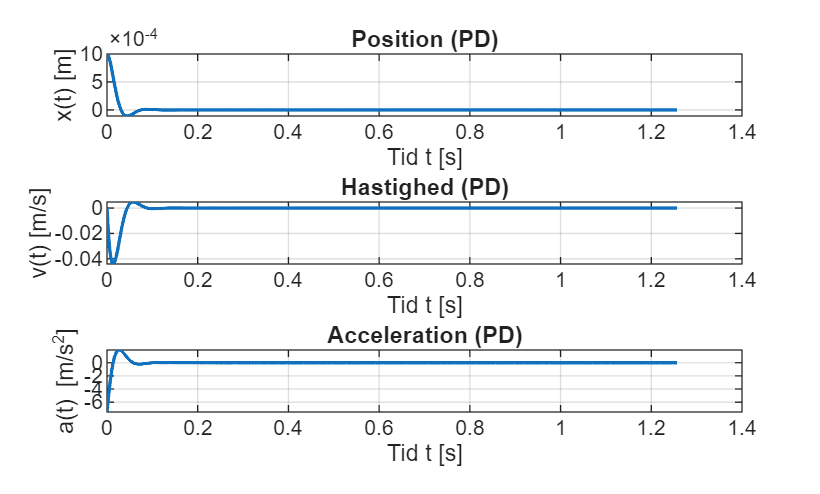

function out = vibration_analysis_system_PD(m, k, c, x0, v0, F_func, t_end, opts)
% VIBRATION_ANALYSIS_SYSTEM_PD
% 2. ordens system med PD-kontrol:
%   m*xdd + c*xd + k*x = F_dist(t) + F_ctrl(t)
%
% PD-kontrol (x_ref = 0):
%   e  = -x
%   ed = -xd
%   F_ctrl = Kp*e + Kd*ed = -Kp*x - Kd*xd
%
% INPUT
%   m,k,c, x0,v0 : systemparametre og initialbetingelser
%   F_func       : disturbance force F_dist(t). Hvis tom -> 0
%   t_end        : (valgfri) simuleringstid, auto hvis tom
%   opts         : (valgfri) struktur:
%       opts.Kp      = 0 (default)
%       opts.Kd      = 0 (default)
%       opts.solver  = "ode45" (default) eller "ode15s"
%       opts.RelTol  = 1e-8 (default)
%       opts.AbsTol  = 1e-10 (default)
%       opts.doPlot  = true/false (default true)
%       opts.verbose = true/false (default true)
%
% OUTPUT
%   out.T, out.X, out.V, out.A, out.Fdist, out.Fctrl, out.Ftotal
%   out.metrics.xPeak, vPeak, aPeak (peak magnitude)
%   out.info: omega_n, zeta, f_n, t_end, (Kp,Kd)

%% --- 0) Defaults ---------------------------------------------------------
if nargin < 6 || isempty(F_func)
    F_func = @(t) zeros(size(t));
end

if nargin < 8 || isempty(opts)
    opts = struct();
end

if ~isfield(opts,"Kp")      || isempty(opts.Kp),      opts.Kp = 0;      end
if ~isfield(opts,"Kd")      || isempty(opts.Kd),      opts.Kd = 0;      end
if ~isfield(opts,"solver")  || isempty(opts.solver),  opts.solver  = "ode45"; end
if ~isfield(opts,"RelTol")  || isempty(opts.RelTol),  opts.RelTol  = 1e-8;    end
if ~isfield(opts,"AbsTol")  || isempty(opts.AbsTol),  opts.AbsTol  = 1e-10;   end
if ~isfield(opts,"doPlot")  || isempty(opts.doPlot),  opts.doPlot  = true;    end
if ~isfield(opts,"verbose") || isempty(opts.verbose), opts.verbose = true;    end

Kp = opts.Kp;
Kd = opts.Kd;

out = struct();
out.params = struct('m',m,'k',k,'c',c,'x0',x0,'v0',v0,'Kp',Kp,'Kd',Kd);

%% --- 1) Afledte størrelser ----------------------------------------------
omega_n = sqrt(k/m);
zeta    = c/(2*sqrt(m*k));
f_n     = omega_n/(2*pi);

out.info = struct('omega_n',omega_n,'zeta',zeta,'f_n',f_n);

if opts.verbose
    fprintf('\n=== Vibration Analysis (PD) ===\n');
    fprintf('omega_n = %.4f rad/s | f_n = %.4f Hz | zeta = %.4f\n', omega_n, f_n, zeta);
    fprintf('PD gains: Kp = %.4g N/m, Kd = %.4g Ns/m\n', Kp, Kd);
end

%% --- 2) Automatisk simuleringstid ---------------------------------------
if nargin < 7 || isempty(t_end)
    if zeta < 1
        omega_d = omega_n*sqrt(1 - zeta^2);
        T_d     = 2*pi/omega_d;
        t_end   = 10*T_d;
    else
        t_end = 10/(max(zeta,1e-6)*omega_n);
    end
end

tspan = [0 t_end];
out.info.t_end = t_end;

%% --- 3) 1. ordens system med PD -----------------------------------------
% y(1)=x, y(2)=v
y0 = [x0; v0];

eom = @(t,y) [ ...
    y(2); ...
    (F_total(t,y) - c*y(2) - k*y(1))/m ];

    function Ft = F_total(t,y)
        % Disturbance
        Fd = F_func(t);
        % PD control (x_ref = 0)
        % e=-x, ed=-v
        Fc = -Kp*y(1) - Kd*y(2);
        Ft = Fd + Fc;
    end

%% --- 4) Solve ------------------------------------------------------------
odeOpts = odeset('RelTol', opts.RelTol, 'AbsTol', opts.AbsTol);

switch lower(string(opts.solver))
    case "ode45"
        [T, Y] = ode45(eom, tspan, y0, odeOpts);
    case "ode15s"
        [T, Y] = ode15s(eom, tspan, y0, odeOpts);
    otherwise
        error('Ukendt solver "%s". Brug "ode45" eller "ode15s".', string(opts.solver));
end

X = Y(:,1);
V = Y(:,2);

% Forces (vectorized eval)
Fdist = F_func(T);
Fctrl = -Kp*X - Kd*V;
Ftot  = Fdist + Fctrl;

A = (Ftot - c*V - k*X)/m;

out.T = T; out.X = X; out.V = V; out.A = A;
out.Fdist = Fdist; out.Fctrl = Fctrl; out.Ftotal = Ftot;

%% --- 5) Metrics ----------------------------------------------------------
out.metrics = struct();
out.metrics.xPeak = peakMetric(T, X);
out.metrics.vPeak = peakMetric(T, V);
out.metrics.aPeak = peakMetric(T, A);

if opts.verbose
    fprintf('\n--- Peak metrics (magnitude) ---\n');
    fprintf('x_peak = %.6g m at t=%.6g s (signed: %.6g)\n', out.metrics.xPeak.mag, out.metrics.xPeak.t, out.metrics.xPeak.value);
    fprintf('v_peak = %.6g m/s at t=%.6g s (signed: %.6g)\n', out.metrics.vPeak.mag, out.metrics.vPeak.t, out.metrics.vPeak.value);
    fprintf('a_peak = %.6g m/s^2 at t=%.6g s (signed: %.6g)\n', out.metrics.aPeak.mag, out.metrics.aPeak.t, out.metrics.aPeak.value);
end

%% --- 6) Plot -------------------------------------------------------------
if opts.doPlot
    figure;

    subplot(3,1,1);
    plot(T, X, 'LineWidth', 1.3);
    grid on; xlabel('Tid t [s]'); ylabel('x(t) [m]'); title('Position (PD)');

    subplot(3,1,2);
    plot(T, V, 'LineWidth', 1.3);
    grid on; xlabel('Tid t [s]'); ylabel('v(t) [m/s]'); title('Hastighed (PD)');

    subplot(3,1,3);
    plot(T, A, 'LineWidth', 1.3);
    grid on; xlabel('Tid t [s]'); ylabel('a(t) [m/s^2]'); title('Acceleration (PD)');
end

end

%% --- helper: peak metric -------------------------------------------------
function pm = peakMetric(T, S)
[mag, idx] = max(abs(S));
pm = struct('t', T(idx), 'mag', mag, 'value', S(idx));
end



% ==== AFPRØVNINGER =====

% Scenarie 1: "Den finder ro"

m = 0.4;          % kg
k = 2000;         % N/m
c = 40;           % Ns/m

x0 = 1e-3;        % 1 mm startforskydning
v0 = 0;           % starter i ro

F_func = [];      % ingen ekstern kraft


% Scenarie 2: "svag rystelse" (sinus-forstyrrelse)

%m = 0.4;
%k = 2000;
%c = 40;           % din rolige løsning

%x0 = 0;
%v0 = 0;

%F0 = 0.3;         % N (svag forstyrrelse)
%f  = 30;          % Hz
%F_func = @(t) F0*sin(2*pi*f*t);

opts.doPlot = true;
opts.verbose = true;

opts.Kp = 1000;            % start
opts.Kd = 0;               % først P-only

outP = vibration_analysis_system_PD(m,k,c,x0,v0,F_func,[],opts);


=== Vibration Analysis (PD) ===
omega_n = 70.7107 rad/s | f_n = 11.2540 Hz | zeta = 0.7071
PD gains: Kp = 1000 N/m, Kd = 30 Ns/m

--- Peak metrics (magnitude) ---
x_peak = 0.001 m at t=0 s (signed: 0.001)
v_peak = 0.0316401 m/s at t=0.0115727 s (signed: -0.0316401)
a_peak = 7.5 m/s^2 at t=0 s (signed: -7.5)


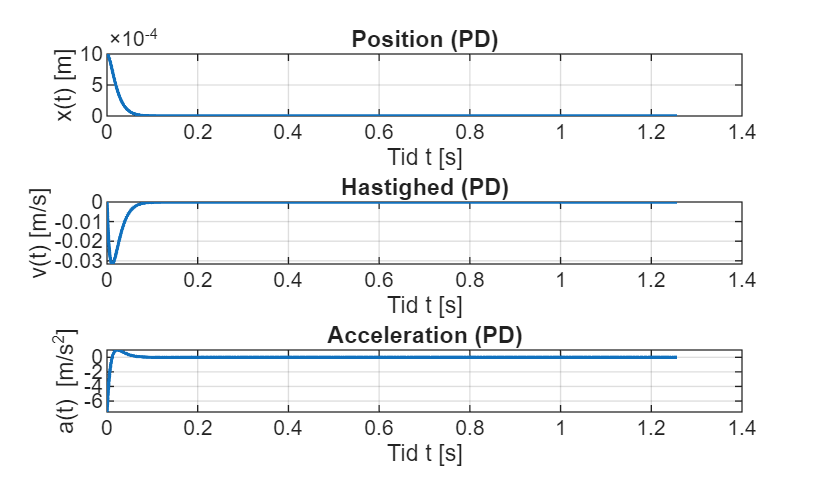


opts.Kd = 30;              % tilføj D
outPD = vibration_analysis_system_PD(m,k,c,x0,v0,F_func,[],opts);